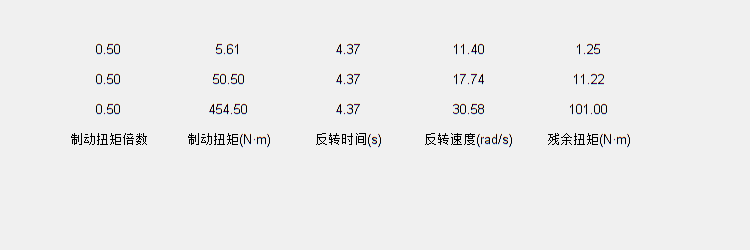

% 假设的数据
data = {
    '制动扭矩倍数', '制动扭矩(N·m)', '反转时间(s)', '反转速度(rad/s)', '残余扭矩(N·m)',
    '0.50', '454.50', '4.37', '30.58', '101.00';
    '0.50', '50.50', '4.37', '17.74', '11.22';
    '0.50', '5.61', '4.37', '11.40', '1.25'
};

% 参数名称
titles = {'制动扭矩倍数', '制动扭矩(N·m)', '反转时间(s)', '反转速度(rad/s)', '残余扭矩(N·m)'};

% 创建图形窗口
fig = figure('Position', [400, 400, 750, 250], 'Name', '参数显示');
% Notice：数值参数左到右分别为窗口中心的在屏幕的x，y坐标，窗口的长宽


%创建文本控件显示数据
for i = 1:size(data, 1)
    for j = 1:size(data, 2)
        txt_data = uicontrol('Style', 'text', ...
            'Position', [50 + (j-1)*120, 100 + (i-1)*30, 120, 20], ... % 第2个数值的步进值最好与第三个相等
            'FontSize', 10, ...
            'HorizontalAlignment', 'center', ...
            'String', data{i, j});
    end
end

% Notice：数值参数左到右对应着元素在窗口的x，y坐标，以及元素的长宽大小
% Notice：此角度上常数项具有新的几何意义
% 研究课题：figure组件内元素的绝对摆放和相对摆放